i =     19750001


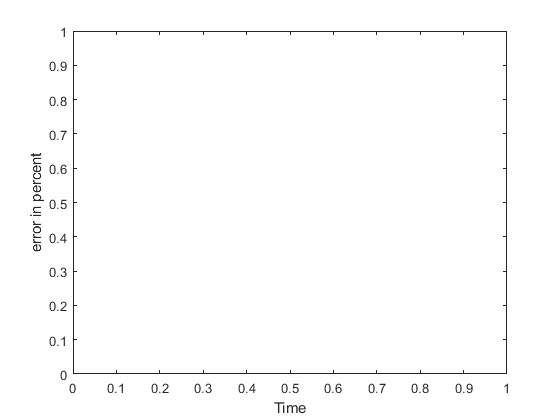

i =     19875001


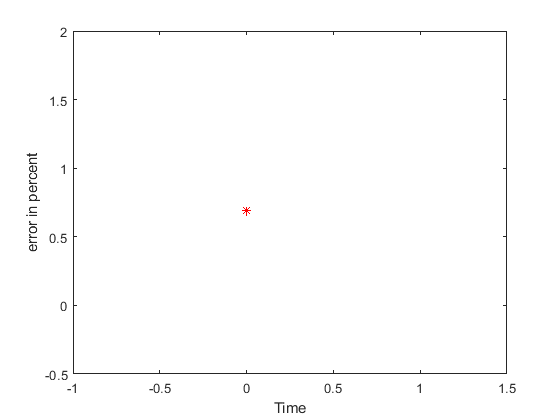

i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


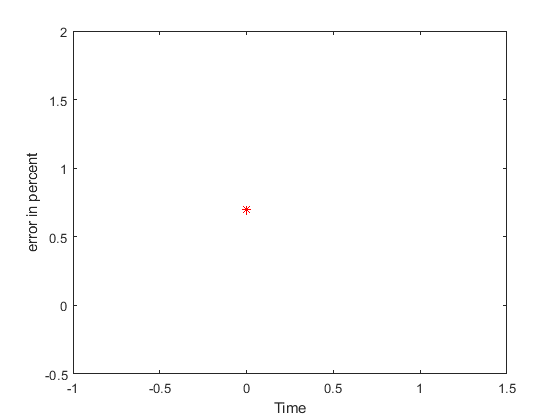

i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


i =     19875001


clear all
fo=1000*1e9;
 fs1=125000;
% fs2=8;
% fs3=12;
T=1/fo;
t2=0:T:(50000000-1)*T;
time1=1*1e-12;
%time=(dis1/100)/1450;

indx1=(time1/T);

 cycles=40;
 freq=2*1e6;
T1=1/freq;
indx=indx1;
t=0:T:2*cycles*T1;
sig=sin((2*pi*freq).*t);

T_mod=2*cycles*T1;
f_mod=(1/T_mod);

l=length(t);
fs=l*f_mod;
Cycles2=0.5;
t1=0:1/fs:Cycles2*T_mod - 1/fs;
sig1=sin((2*pi*f_mod).*t1);
for x=1:length(t1)
    chirp(indx)=1000*sig1(x).*sig(x);
    indx=indx+1;
%     B(x)=i*(sig1(x).*sig(x));
end
t3=0:T:t2(indx-1);
p=1;
for i=1:fs1:length(chirp)-fs1
    chirp_new(p)=chirp(i);
    p=p+1;
end
% for i=1:length(chirp_new)
%     if chirp_new(i) ~= 0 
%         break;
%     end
% end

indx2=abs(indx1-i);
t4=t2(indx2):T:t2(indx2+(length(chirp_new)-1));
[r]= three_points(chirp_new,t4);
[i_y(:,1),pp]=interpolate(r);
sample_time=T;
%time_inter(:,1)=r(:,5)+(pp)'*sample_time;
g=1;
for a=1:20:1000
time2(g)=a*1e-12;
indx1(g)=uint32((time2(g)/T));
indx=indx1(g);
for x=1:length(t1)
    chirp1(indx)=1000*sig1(x).*sig(x);
    indx=indx+1;
%     B(x)=i*(sig1(x).*sig(x));
end
t3=0:T:t2(indx-1);

p=1;
for i=1:fs1:length    (chirp1)-fs1
    chirp_new1(p)=chirp1(i);
    p=p+1;  
end
% for i=1:length(chirp_new1)
%     if chirp_new1(i) ~= 0 
%         break;
%     end
% end
i
indx2=abs(indx1-i);
t4=t2(indx2):T:t2(indx2+(length(chirp_new1)-1));
[r1]= three_points(chirp_new1,t4);
[i_y1(:,g),pp1]=interpolate(r1);
sample_time=1/(2*1e6);
% time_inter(:,1)=r(:,5)+(pp1)'*sample_time;
[c1,lags1]=xcorr(i_y1(:,g),i_y(:,1));
c=c1./max(abs(c1(:)));
%lags=lags1/(8*1e6);
lags=lags1;
figure(g),stem(lags,c);
max_cor(g)=max(c);
 ind=find(c==max_cor(g));
ind4=ind;
 time_cor(g)=lags(ind);
 zm1(g)=c(ind-1);
 zp1(g)=c(ind+1);
 [i_cor,p_cor(g)]=interpolate([zm1(g) max_cor(g) zp1(g)]);
%  time_final(g)=(p_cor(g)*(1/(8*1e6)))+time_cor(g);
  time_final1(g)=p_cor(g)+time_cor(g);
  time_final(g)=time_final1(g)/(2*1e6);
 time_cor_final(g)=time_cor(g)+time_final(g)+52.641*1e-6;
 expected(g)=time2(g)-time1;
 error(g)=expected(g)-time_final(g);
 error_percent(g)=((expected(g)-time_final(g))/expected(g))*100;
  plot(time2(g),error_percent(g),'r-*');
     xlabel('Time');
     ylabel("error in percent");
      hold on;
 g=g+1; 
 clearvars chirp1 chirp_new1 apnd_zeros chirp_new c1 lags1 lags t4 indx
end